# Taratura manuale dell'anello di posizione

Determinare $C(s)$ in modo che soddisfi una frequenza di taglio desirata

In quest'esempio il controllore è un PI


$$C(s)=PI(s)=\frac{K_p\cdot s+K_i}{s}=K_p\left(1+\frac{1}{T_i s}\right)=K_p \frac{T_i s +1}{T_i s}$$


il processo è la funzione di trasferimento, in questo caso velocità-posizione lato motore

clear all;close all;clc;
controllori_velocita;

Ts=1e-3;
s=tf('s');
% creiamo il nuovo modello
Lcv = Cv1*notchv1*P1;
sys_pos=feedback(Lcv,1)*1/s;%(Lcv/(1+Lcv))


Con funzione di trasferimento

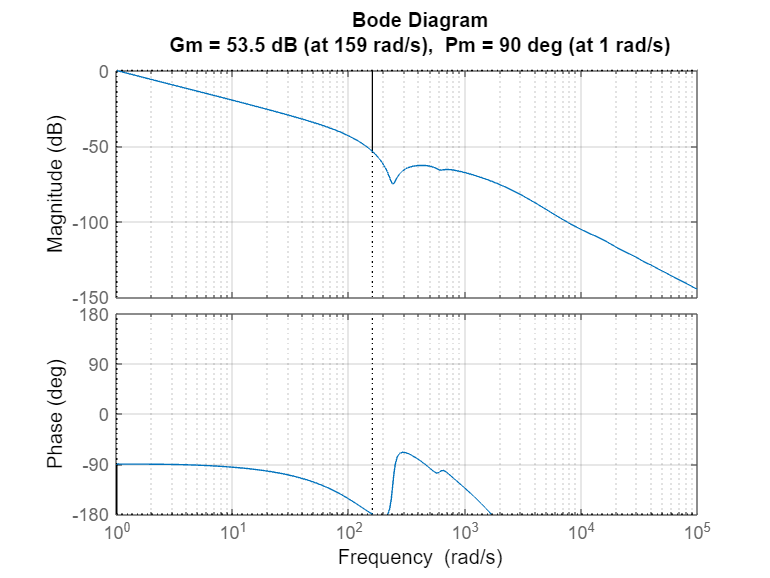

figure
margin(sys_pos)
grid on;
xlim([1 100000])
ylim([-180 180])

Vorrei un $\omega_c$ prossima all'antirisonanza (che è attorno a 200 rad/s)

wc=150;

L'azione integrale mi sfasa, la metto almeno una decade prima.

wi=wc/20; % pulsazione azione integrale
Ti=1/wi

Ti = 0.1333

Il mio controllore sarà


$$C(s)=K_p \left(1+1/(Ti\cdot s)\right)=K_p C_o(s)$$


con $C_o(s)=$

s=tf('s');
Co=1;%+1/(Ti*s);

Calcolo $K_p$ in modo che $C(s)*P(s)=K_p \left(C_o(s)*P(s)\right)$ abbia modulo 1 in $\omega_c$. 

$|K_p \left(C_o(j\omega_c)*P(j\omega_c)\right)|=1 $ quindi $K_p=1/| \left(C_o(j\omega_c)*P(j\omega_c)\right)|$


Kp=1/abs(freqresp(Co*sys_pos,wc));%abs(freqresp(Co*sys_pos,wc));%1/abs(freqresp(Co*sys_pos,wc))
C=Kp*Co

C = 387.6481

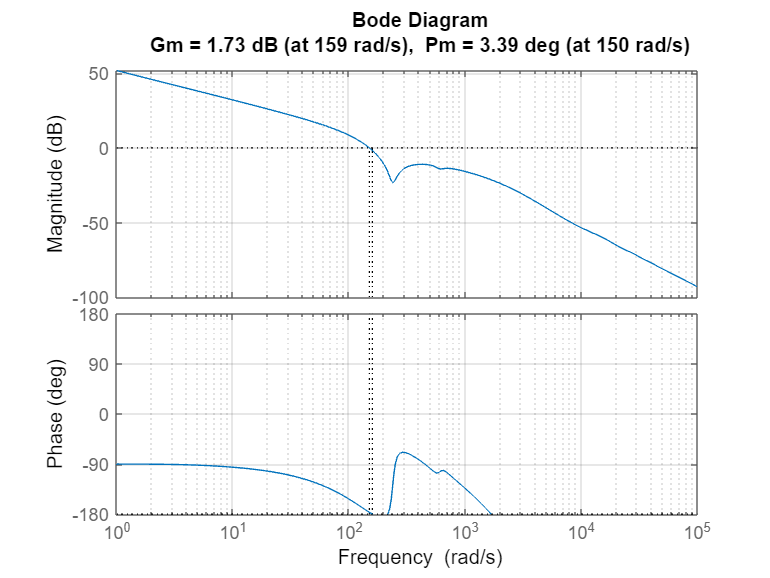

figure
margin(C*sys_pos)
grid on
xlim([1 100000])
ylim([-180 180])

Il diagramma di bode taglia più volte, meglio aggiungere un filtro per abbassare il picco.

#### Filtro Notch

Un filtro notch è un'elimina banda. La zona da eliminare è 

damp(sys_pos)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  0.00e+00                -1.00e+00       0.00e+00              Inf    
 -4.19e+00                 1.00e+00       4.19e+00         2.38e-01    
 -1.76e+02 + 3.38e+01i     9.82e-01       1.79e+02         5.70e-03    
 -1.76e+02 - 3.38e+01i     9.82e-01       1.79e+02         5.70e-03    
 -7.78e+01 + 6.00e+02i     1.29e-01       6.05e+02         1.28e-02    
 -7.78e+01 - 6.00e+02i     1.29e-01       6.05e+02         1.28e-02    
 -9.80e+02                 1.00e+00       9.80e+02         1.02e-03    


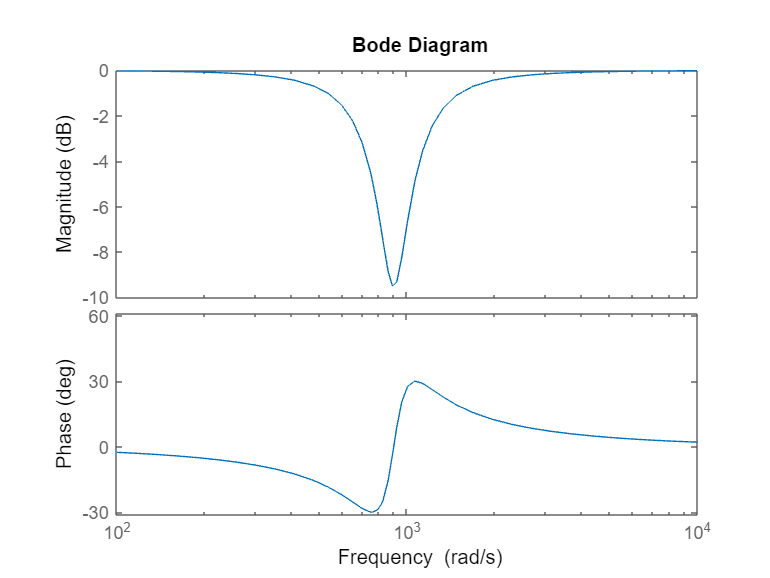

wn=900;
xci_z=0.1; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.3;
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2);
figure
bode(notch)

Per il PI, il "nuovo" sistema da controllare è

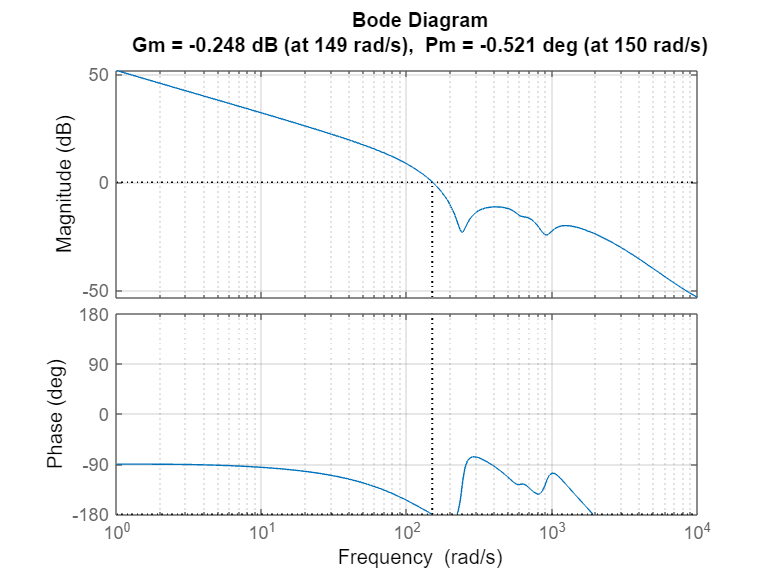

P=sys_pos*notch;
Kp=1/abs(freqresp(Co*P,wc));
C=Kp*Co;
figure
margin(C*P)
ylim([-180 180])
grid on

Potrei voler aggiungere altri poli (ad esempio un passa basso)